# Ottimizzazione del turbofan con gas generator dato

clear all, close all, clc

%%qualità componenti
q.e02 = 1;
q.pi12 = 1;
q.efan = 1;
q.e23 = 1;
q.eq = 1;
q.piCC = 1;
q.e445 = 1; %efficienza della turbina di alta pressione
q.e455 = 1; %efficienza della turbina di bassa pressione

% parametri ugelli: è possibile scegliere se la loro forma è convergente
% o convergente divergente, e nel secondo caso specificare il rapporto tra
% le aree
u.nozzle = "conv";
u.epsi = 30;
u.nozzle1 = "conv";
u.epsi1 = 30;

% condizioni di volo, fc sta per flight conditions
fc.M0 = 0.88;
fc.h = 11000;
[fc.P0, fc.T0, fc.rho0] = ISA(fc.h);
fc.g = 1.4;
fc.ge = 1.33; %gamma  dei prodotti di combustione
fc.R = 287;
fc.Re = 277.13; %R/massa molare dei prodotti di combustione
fc.m = 44;
fc.L = 42000000;

nvars = 2;
fc.TIT = 1600/273.15;
fc.OPR = 10;
lb = [0, 1];
ub = [10, 10];
x0 = [1,1.5];

# Anticipazione grafica:

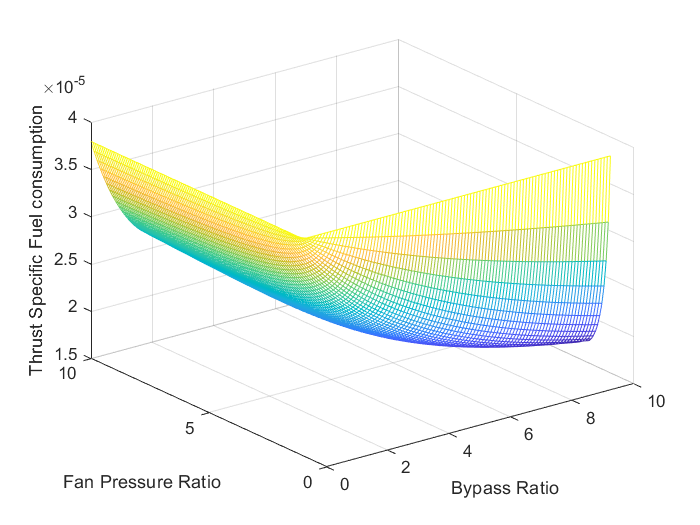

x = linspace(lb(1), ub(1));
y = linspace(lb(2), ub(2));
[X,Y] = meshgrid(x,y);
for a = 1:length(x)
    % x(a) è il BPR
    for b = 1:length(y)
        % y(b) è il FPR
        [temp1, temp2, valid] = grafic_prestazioni([x(a), y(b)],q,u,fc);
        if valid
            isp(b,a) = temp1;   %Lungo le righe cambia il FPR, lungo le colonne cambia il BPR
            tsfc(b,a) = temp2;
        else
            isp(b,a) = nan;
            tsfc(b,a) = nan;
        end
    end
end

f1 = figure;
mesh(X,Y,tsfc)
hold on
xlabel('Bypass Ratio')
ylabel('Fan Pressure Ratio')
zlabel('Thrust Specific Fuel consumption')

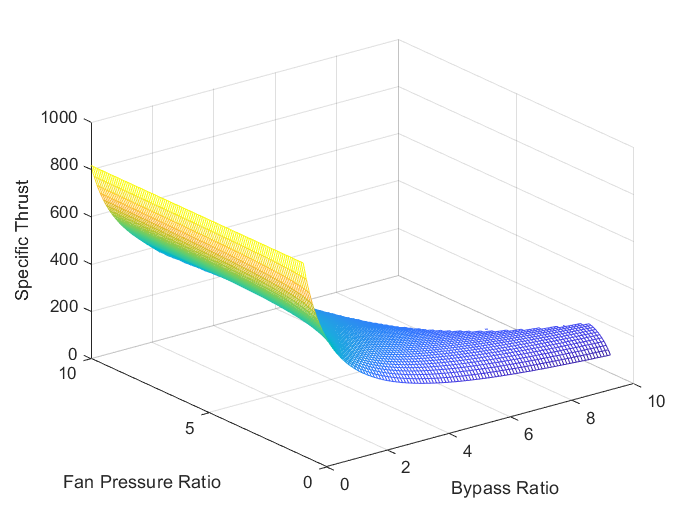


f2 = figure;
mesh(X,Y,isp)
xlabel('Bypass Ratio')
ylabel('Fan Pressure Ratio')
zlabel('Specific Thrust')

## Punti di adattamento:

% x = linspace(lb(1), ub(1));
% y = linspace(lb(2), ub(2));
% [X,Y] = meshgrid(x,y);
% for a = 1:length(x)
%     % x(a) è il BPR
%     for b = 1:length(y)
%         % y(b) è il FPR
%         [temp1, temp2, valid, adapt] = adapt_prestazioni([x(a), y(b)],q,u,fc);
%         if valid
%             isp(b,a) = temp1;   %Lungo le righe cambia il FPR, lungo le colonne cambia il BPR
%             tsfc(b,a) = temp2;
%             if adapt(1)
%                 ispad(b,a) = temp1;
%                 tsfcad(b,a) = temp2;
%             else 
%                 ispad(b,a) = nan;
%                 tsfcad(b,a) = nan;
%             end
%             if adapt(2)
%                 ispad1(b,a) = temp1;
%                 tsfcad1(b,a) = temp2;
%             else 
%                 ispad1(b,a) = nan;
%                 tsfcad1(b,a) = nan;
%             end
%         else
%             isp(b,a) = nan;
%             tsfc(b,a) = nan;
%         end
%     end
% end
% 
% f1 = figure;
% mesh(X,Y,tsfc)
% hold on
% plot3(X,Y,tsfcad,'o', X,Y,tsfcad1,'*')
% xlabel('Bypass Ratio')
% ylabel('Fan Pressure Ratio')
% zlabel('Thrust Specific Fuel consumption')

# Ottimizzazione del TSFC:

% Pass fixed parameters to objfun
objfun2 = @(vars)tsfcfobj2(vars,q,u,fc,f1);

% Pass fixed parameters to confun
confun2 = @(vars)nonlcon2(vars,fc,q);

% Set nondefault solver options
options2 = optimoptions('ga','Display','iter');

% Solve
[solution,objectiveValue] = ga(objfun2,nvars,[],[],[],[],lb,ub,confun2,[],...
    options2);


                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations



% Clear variables
clearvars objfun2 confun2 options2

function [Isp, TSFC, valid] = grafic_prestazioni(vars, q, u, fc)
    
    OPR = fc.OPR;
    TIT = fc.TIT;
    BPR = vars(1);
    FPR = vars(2);
    if BPR == 0  %qui una piccola sovrascrizione, inevitabile, in quanto FPR è ovviamente 0 quando BPR è 0, ma FPR impone il lavoro svolto dalla turbina di bassa pressione
        FPR = 0;
    end
    
    T4t = TIT*273.15;
    
    Cp = fc.R*fc.g/(fc.g-1);
    Cpe = fc.Re*fc.ge/(fc.ge-1);
    V0 = fc.M0*sqrt(fc.g*fc.R*fc.T0);
    T0t = fc.T0*(1 + (fc.g-1)*(fc.M0^2)/2);
    P0t = fc.P0*(1+ (fc.g-1)*(fc.M0^2)/2)^(fc.g/(fc.g-1));
    %diffusore
    if q.e02 ~= 1             %if q.e02 is not given, for M<1 the pressures are q.equal and for M>1 && M<5 the pressures are given by a relation from MIL-E-5007-D
        P2t = fc.P0*(1+ q.e02*(fc.g-1)*(fc.M0^2)/2)^(fc.g/(fc.g-1));
    elseif fc.M0>1 && fc.M0<5         %% only if supersonic
        P1t = P0t*(1-0.076*(fc.M0-1)^1.35);
        P2t = P1t*q.pi12;
    else
        P1t = P0t;
        P2t = P1t*q.pi12;
    end
    T2t = T0t;      %supponiamo l'ingresso adiabatico
    
    %fan
    P13t = P2t*FPR;
    T13t = T2t*(1+(FPR^((fc.g-1)/fc.g) - 1)/q.efan);
    Wf = fc.m*BPR*Cp*(T13t-T2t);
    
    %compressore
    P3t = P2t*OPR;
    T3t = T2t*(1 + (OPR^((fc.g-1)/fc.g) - 1)/q.e23);
    Wc = fc.m*Cp*(T3t-T2t);
    
    %camera di combustione, supponendo che la temperatura di iniezione del
    %combustibile sia la stessa di T3t, la quale è approssimata a T3 in
    %quanto il Mach in questa sezione è prossimo a zero e quindi possiamo
    %approssimare senza perdite eccessive di precisione
    
    f = (Cpe*T4t - Cp*T3t)/(q.eq*fc.L - Cpe*T4t + Cp*T3t);
    c = f*fc.m;
    me = fc.m + c;
    P4t = P3t*q.piCC;
    
    %turbina
    T45t = T4t-Wc/(me*Cpe);
    P45t = P4t*(1- (1-T45t/T4t)/q.e445)^(fc.ge/(fc.ge-1));
    T5t = T45t - Wf/(me*Cpe);
    P5t = P45t*(1- (1-T5t/T45t)/q.e455)^(fc.ge/(fc.ge-1));
    
    %controllo se la pressione P5t è maggiore della pressione ambiente
    %Questo check è utile quando siamo in assetto 2, se siamo in assetto 1
    %è inutile in quanto lo svolge la function nonlcon
    valid = true;
    esp = (fc.g-1)/fc.g;
    espe = (fc.ge)/(fc.ge -1);
    if fc.P0 - P2t*OPR*((1 - Cp*T2t*(OPR^esp -1)/((1+f)*Cpe*q.e445*T4t*q.e23))^espe)*(1 - Cp*T2t*BPR*(FPR^esp - 1)/((1+f)*Cpe*q.e455*q.efan*(T4t - Cp*T2t*(OPR^esp - 1)/((1+f)*Cpe*q.e23))))^espe > 0
        valid = false;
    end
    
    %ugello primario
    if u.nozzle == "conv"
        adapted = false;
        if P5t/fc.P0 <= ((fc.ge+1)/2)^(fc.ge/(fc.ge-1))
            adapted = true;
            Ps = fc.P0;
        end
        if adapted
            Ts = T5t*(fc.P0/P5t)^((fc.ge-1)/fc.ge);
            Ms = sqrt((2/(fc.ge-1))*((P5t/fc.P0)^((fc.ge-1)/fc.ge)-1));
            Vs = Ms*sqrt(fc.ge*fc.Re*Ts);
        else
            Ps = P5t/((fc.ge+1)/2)^(fc.ge/(fc.ge-1));
            Ts = T5t*2/(fc.ge+1);
            Ms = 1;
            Vs = sqrt(fc.ge*fc.Re*Ts);
        end
        As = me/(Vs*Ps/(fc.Re*Ts));
    elseif u.nozzle == "condiv"
        adapted = false; %tratto l'ugello sempre come non adattato, al massimo al calcolo della spinta si elimineranno le due pressioni
        %%per ugello non adattato è necessaria la risoluzione di una
        %%q.equazione non lineare
        G = sqrt(fc.ge)*(2/(fc.ge+1))^((fc.ge+1)/(2*(fc.ge-1)));
        maxeval = 50;
        NPR = 0;
        for i=1:maxeval
            oldNPR = NPR;
            NPR = (G/(u.epsi*sqrt((2*fc.ge/(fc.ge-1))*(1-NPR^((fc.ge-1)/fc.ge)))))^fc.ge;
            if norm((NPR-oldNPR))*100/NPR < 0.1
                i = maxeval;
            end
        end
        Ps = NPR*P5t;
        Ts = T5t*NPR^((fc.ge-1)/fc.ge);
        Ms = sqrt((2/(fc.ge-1))*(T5t/Ts -1));
        Vs = Ms*sqrt(fc.ge*fc.Re*Ts);
        As = me/(Vs*Ps/(fc.Re*Ts));
    end
    %ugello secondario
    if BPR ~= 0
        if u.nozzle1 == "conv"
            adapted1 = false;
            if P13t/fc.P0 <= ((fc.g+1)/2)^(fc.g/(fc.g-1))
                adapted1 = true;
                P1s = fc.P0;
            end
            if adapted1
                T1s = T13t*(fc.P0/P13t)^((fc.g-1)/fc.g);
                M1s = sqrt((2/(fc.g-1))*((P13t/fc.P0)^((fc.g-1)/fc.g)-1));
                V1s = M1s*sqrt(fc.g*fc.R*T1s);
            else
                P1s = P13t/((fc.g+1)/2)^(fc.g/(fc.g-1));
                T1s = T13t*2/(fc.g+1);
                M1s = 1;
                V1s = sqrt(fc.g*fc.R*T1s);
            end
            A1s = fc.m*BPR/(V1s*P1s/(fc.R*T1s));
        elseif u.nozzle1 == "condiv"
            adapted1 = false; %tratto l'ugello sempre come non adattato, al massimo al calcolo della spinta si elimineranno le due pressioni
            %%per ugello non adattato è necessaria la risoluzione di una
            %%q.equazione non lineare
            G = sqrt(fc.g)*(2/(fc.g+1))^((fc.g+1)/(2*(fc.g-1)));
            maxeval = 50;
            NPR1 = 0;
            for i=1:maxeval
                oldNPR1 = NPR1;
                NPR1 = (G/(u.epsi1*sqrt((2*fc.g/(fc.g-1))*(1-NPR1^((fc.g-1)/fc.g)))))^fc.g;
                if (NPR1-oldNPR1)*100/NPR1 < 0.1
                    i = maxeval;
                end
            end
            P1s = NPR1*P13t;
            T1s = T13t*NPR1^((fc.g-1)/fc.g);
            M1s = sqrt((2/(fc.g-1))*(T13t/T1s -1));
            V1s = M1s*sqrt(fc.g*fc.R*T1s);
            A1s = m1/(V1s*P1s/(fc.R*T1s));
        end
    else
        A1s = 0;
        P1s = 0;
        V1s = 0;
    end
    
    %Potrebbe succedere che l'espansione sia tale da avere Temperature di
    %uscita negative, quindi effettuiamo un check rispetto alla Temperatura
    %minima raggiungibile, che è quella del Turbojet corrispondente partendo 
    %dalla stazione "45"
    %Anche qui, inutile nel momento in cui siamo in assetto 1

    if Ts < (fc.P0^((fc.ge-1)/fc.ge))*(T4t - Cp*T2t*(OPR^(esp) -1)/((1+f)*Cpe*q.e23))/(((OPR*P2t)^((fc.ge-1)/fc.ge))*(1 - (Cp*T2t)*(OPR^(esp) -1)/((1+f)*q.e445*T4t*Cpe*q.e23))) 
        valid = false;
    end
    
    %prestazioni
    E = me*Vs- fc.m*V0 + As*(Ps-fc.P0) + fc.m*BPR*(V1s-V0) + A1s*(P1s-fc.P0);
    Isp = E/(me + fc.m*BPR);
    if Isp <0
        valid = false;
    end
    TSFC = c/E;

end

function [TSFC] = prestazioni(vars, q, u, fc)
    
    OPR = fc.OPR;
    TIT = fc.TIT;
    BPR = vars(1);
    FPR = vars(2);
    if BPR == 0  %qui una piccola sovrascrizione, inevitabile, in quanto FPR è ovviamente 0 quando BPR è 0, ma FPR impone il lavoro svolto dalla turbina di bassa pressione
        FPR = 0;
    end
    
    T4t = TIT*273.15;
    
    Cp = fc.R*fc.g/(fc.g-1);
    Cpe = fc.Re*fc.ge/(fc.ge-1);
    V0 = fc.M0*sqrt(fc.g*fc.R*fc.T0);
    T0t = fc.T0*(1 + (fc.g-1)*(fc.M0^2)/2);
    P0t = fc.P0*(1+ (fc.g-1)*(fc.M0^2)/2)^(fc.g/(fc.g-1));
    %diffusore
    if q.e02 ~= 1             %if q.e02 is not given, for M<1 the pressures are q.equal and for M>1 && M<5 the pressures are given by a relation from MIL-E-5007-D
        P2t = fc.P0*(1+ q.e02*(fc.g-1)*(fc.M0^2)/2)^(fc.g/(fc.g-1));
    elseif fc.M0>1 && fc.M0<5         %% only if supersonic
        P1t = P0t*(1-0.076*(fc.M0-1)^1.35);
        P2t = P1t*q.pi12;
    else
        P1t = P0t;
        P2t = P1t*q.pi12;
    end
    T2t = T0t;      %supponiamo l'ingresso adiabatico
    
    %fan
    P13t = P2t*FPR;
    T13t = T2t*(1+(FPR^((fc.g-1)/fc.g) - 1)/q.efan);
    Wf = fc.m*BPR*Cp*(T13t-T2t);
    
    %compressore
    P3t = P2t*OPR;
    T3t = T2t*(1 + (OPR^((fc.g-1)/fc.g) - 1)/q.e23);
    Wc = fc.m*Cp*(T3t-T2t);
    
    %camera di combustione, supponendo che la temperatura di iniezione del
    %combustibile sia la stessa di T3t, la quale è approssimata a T3 in
    %quanto il Mach in questa sezione è prossimo a zero e quindi possiamo
    %approssimare senza perdite eccessive di precisione
    
    f = (Cpe*T4t - Cp*T3t)/(q.eq*fc.L - Cpe*T4t + Cp*T3t);
    c = f*fc.m;
    me = fc.m + c;
    P4t = P3t*q.piCC;
    
    %turbina
    T45t = T4t-Wc/(me*Cpe);
    P45t = P4t*(1- (1-T45t/T4t)/q.e445)^(fc.ge/(fc.ge-1));
    T5t = T45t - Wf/(me*Cpe);
    P5t = P45t*(1- (1-T5t/T45t)/q.e455)^(fc.ge/(fc.ge-1));
    
    %ugello primario
    if u.nozzle == "conv"
        adapted = false;
        if P5t/fc.P0 <= ((fc.ge+1)/2)^(fc.ge/(fc.ge-1))
            adapted = true;
            Ps = fc.P0;
        end
        if adapted
            Ts = T5t*(fc.P0/P5t)^((fc.ge-1)/fc.ge);
            Ms = sqrt((2/(fc.ge-1))*((P5t/fc.P0)^((fc.ge-1)/fc.ge)-1));
            Vs = Ms*sqrt(fc.ge*fc.Re*Ts);
        else
            Ps = P5t/((fc.ge+1)/2)^(fc.ge/(fc.ge-1));
            Ts = T5t*2/(fc.ge+1);
            Ms = 1;
            Vs = sqrt(fc.ge*fc.Re*Ts);
        end
        As = me/(Vs*Ps/(fc.Re*Ts));
    elseif u.nozzle == "condiv"
        adapted = false; %tratto l'ugello sempre come non adattato, al massimo al calcolo della spinta si elimineranno le due pressioni
        %%per ugello non adattato è necessaria la risoluzione di una
        %%q.equazione non lineare
        G = sqrt(fc.ge)*(2/(fc.ge+1))^((fc.ge+1)/(2*(fc.ge-1)));
        maxeval = 50;
        NPR = 0;
        for i=1:maxeval
            oldNPR = NPR;
            NPR = (G/(u.epsi*sqrt((2*fc.ge/(fc.ge-1))*(1-NPR^((fc.ge-1)/fc.ge)))))^fc.ge;
            if norm((NPR-oldNPR))*100/NPR < 0.1
                i = maxeval;
            end
        end
        Ps = NPR*P5t;
        Ts = T5t*NPR^((fc.ge-1)/fc.ge);
        Ms = sqrt((2/(fc.ge-1))*(T5t/Ts -1));
        Vs = Ms*sqrt(fc.ge*fc.Re*Ts);
        As = me/(Vs*Ps/(fc.Re*Ts));
    end
    %ugello secondario
    if BPR ~= 0
        if u.nozzle1 == "conv"
            adapted1 = false;
            if P13t/fc.P0 <= ((fc.g+1)/2)^(fc.g/(fc.g-1))
                adapted1 = true;
                P1s = fc.P0;
            end
            if adapted1
                T1s = T13t*(fc.P0/P13t)^((fc.g-1)/fc.g);
                M1s = sqrt((2/(fc.g-1))*((P13t/fc.P0)^((fc.g-1)/fc.g)-1));
                V1s = M1s*sqrt(fc.g*fc.R*T1s);
            else
                P1s = P13t/((fc.g+1)/2)^(fc.g/(fc.g-1));
                T1s = T13t*2/(fc.g+1);
                M1s = 1;
                V1s = sqrt(fc.g*fc.R*T1s);
            end
            A1s = fc.m*BPR/(V1s*P1s/(fc.R*T1s));
        elseif u.nozzle1 == "condiv"
            adapted1 = false; %tratto l'ugello sempre come non adattato, al massimo al calcolo della spinta si elimineranno le due pressioni
            %%per ugello non adattato è necessaria la risoluzione di una
            %%q.equazione non lineare
            G = sqrt(fc.g)*(2/(fc.g+1))^((fc.g+1)/(2*(fc.g-1)));
            maxeval = 50;
            NPR1 = 0;
            for i=1:maxeval
                oldNPR1 = NPR1;
                NPR1 = (G/(u.epsi1*sqrt((2*fc.g/(fc.g-1))*(1-NPR1^((fc.g-1)/fc.g)))))^fc.g;
                if (NPR1-oldNPR1)*100/NPR1 < 0.1
                    i = maxeval;
                end
            end
            P1s = NPR1*P13t;
            T1s = T13t*NPR1^((fc.g-1)/fc.g);
            M1s = sqrt((2/(fc.g-1))*(T13t/T1s -1));
            V1s = M1s*sqrt(fc.g*fc.R*T1s);
            A1s = m1/(V1s*P1s/(fc.R*T1s));
        end
    else
        A1s = 0;
        P1s = 0;
        V1s = 0;
    end
    
    %prestazioni
    E = me*Vs- fc.m*V0 + As*(Ps-fc.P0) + fc.m*BPR*(V1s-V0) + A1s*(P1s-fc.P0);
    Isp = E/(me + fc.m*BPR);
    TSFC = c/E;

end

function [Isp, TSFC, valid, adapt] = adapt_prestazioni(vars, q, u, fc)
    
    OPR = fc.OPR;
    TIT = fc.TIT;
    BPR = vars(1);
    FPR = vars(2);
    if BPR == 0  %qui una piccola sovrascrizione, inevitabile, in quanto FPR è ovviamente 0 quando BPR è 0, ma FPR impone il lavoro svolto dalla turbina di bassa pressione
        FPR = 0;
    end
    
    T4t = TIT*273.15;
    
    Cp = fc.R*fc.g/(fc.g-1);
    Cpe = fc.Re*fc.ge/(fc.ge-1);
    V0 = fc.M0*sqrt(fc.g*fc.R*fc.T0);
    T0t = fc.T0*(1 + (fc.g-1)*(fc.M0^2)/2);
    P0t = fc.P0*(1+ (fc.g-1)*(fc.M0^2)/2)^(fc.g/(fc.g-1));
    %diffusore
    if q.e02 ~= 1             %if q.e02 is not given, for M<1 the pressures are q.equal and for M>1 && M<5 the pressures are given by a relation from MIL-E-5007-D
        P2t = fc.P0*(1+ q.e02*(fc.g-1)*(fc.M0^2)/2)^(fc.g/(fc.g-1));
    elseif fc.M0>1 && fc.M0<5         %% only if supersonic
        P1t = P0t*(1-0.076*(fc.M0-1)^1.35);
        P2t = P1t*q.pi12;
    else
        P1t = P0t;
        P2t = P1t*q.pi12;
    end
    T2t = T0t;      %supponiamo l'ingresso adiabatico
    
    %fan
    P13t = P2t*FPR;
    T13t = T2t*(1+(FPR^((fc.g-1)/fc.g) - 1)/q.efan);
    Wf = fc.m*BPR*Cp*(T13t-T2t);
    
    %compressore
    P3t = P2t*OPR;
    T3t = T2t*(1 + (OPR^((fc.g-1)/fc.g) - 1)/q.e23);
    Wc = fc.m*Cp*(T3t-T2t);
    
    %camera di combustione, supponendo che la temperatura di iniezione del
    %combustibile sia la stessa di T3t, la quale è approssimata a T3 in
    %quanto il Mach in questa sezione è prossimo a zero e quindi possiamo
    %approssimare senza perdite eccessive di precisione
    
    f = (Cpe*T4t - Cp*T3t)/(q.eq*fc.L - Cpe*T4t + Cp*T3t);
    c = f*fc.m;
    me = fc.m + c;
    P4t = P3t*q.piCC;
    
    %turbina
    T45t = T4t-Wc/(me*Cpe);
    P45t = P4t*(1- (1-T45t/T4t)/q.e445)^(fc.ge/(fc.ge-1));
    T5t = T45t - Wf/(me*Cpe);
    P5t = P45t*(1- (1-T5t/T45t)/q.e455)^(fc.ge/(fc.ge-1));
    
    %controllo se la pressione P5t è maggiore della pressione ambiente
    %Questo check è utile quando siamo in assetto 2, se siamo in assetto 1
    %è inutile in quanto lo svolge la function nonlcon
    valid = true;
    esp = (fc.g-1)/fc.g;
    espe = (fc.ge)/(fc.ge -1);
    if fc.P0 - P2t*OPR*((1 - Cp*T2t*(OPR^esp -1)/((1+f)*Cpe*q.e445*T4t*q.e23))^espe)*(1 - Cp*T2t*BPR*(FPR^esp - 1)/((1+f)*Cpe*q.e455*q.efan*(T4t - Cp*T2t*(OPR^esp - 1)/((1+f)*Cpe*q.e23))))^espe > 0
        valid = false;
    end
    
    %ugello primario
    if u.nozzle == "conv"
        adapted = false;
        if P5t/fc.P0 <= ((fc.ge+1)/2)^(fc.ge/(fc.ge-1))
            adapted = true;
            Ps = fc.P0;
        end
        if adapted
            Ts = T5t*(fc.P0/P5t)^((fc.ge-1)/fc.ge);
            Ms = sqrt((2/(fc.ge-1))*((P5t/fc.P0)^((fc.ge-1)/fc.ge)-1));
            Vs = Ms*sqrt(fc.ge*fc.Re*Ts);
        else
            Ps = P5t/((fc.ge+1)/2)^(fc.ge/(fc.ge-1));
            Ts = T5t*2/(fc.ge+1);
            Ms = 1;
            Vs = sqrt(fc.ge*fc.Re*Ts);
        end
        As = me/(Vs*Ps/(fc.Re*Ts));
    elseif u.nozzle == "condiv"
        adapted = false; %tratto l'ugello sempre come non adattato, al massimo al calcolo della spinta si elimineranno le due pressioni
        %%per ugello non adattato è necessaria la risoluzione di una
        %%q.equazione non lineare
        G = sqrt(fc.ge)*(2/(fc.ge+1))^((fc.ge+1)/(2*(fc.ge-1)));
        maxeval = 50;
        NPR = 0;
        for i=1:maxeval
            oldNPR = NPR;
            NPR = (G/(u.epsi*sqrt((2*fc.ge/(fc.ge-1))*(1-NPR^((fc.ge-1)/fc.ge)))))^fc.ge;
            if norm((NPR-oldNPR))*100/NPR < 0.1
                i = maxeval;
            end
        end
        Ps = NPR*P5t;
        Ts = T5t*NPR^((fc.ge-1)/fc.ge);
        Ms = sqrt((2/(fc.ge-1))*(T5t/Ts -1));
        Vs = Ms*sqrt(fc.ge*fc.Re*Ts);
        As = me/(Vs*Ps/(fc.Re*Ts));
    end
    %ugello secondario
    if BPR ~= 0
        if u.nozzle1 == "conv"
            adapted1 = false;
            if P13t/fc.P0 <= ((fc.g+1)/2)^(fc.g/(fc.g-1))
                adapted1 = true;
                P1s = fc.P0;
            end
            if adapted1
                T1s = T13t*(fc.P0/P13t)^((fc.g-1)/fc.g);
                M1s = sqrt((2/(fc.g-1))*((P13t/fc.P0)^((fc.g-1)/fc.g)-1));
                V1s = M1s*sqrt(fc.g*fc.R*T1s);
            else
                P1s = P13t/((fc.g+1)/2)^(fc.g/(fc.g-1));
                T1s = T13t*2/(fc.g+1);
                M1s = 1;
                V1s = sqrt(fc.g*fc.R*T1s);
            end
            A1s = fc.m*BPR/(V1s*P1s/(fc.R*T1s));
        elseif u.nozzle1 == "condiv"
            adapted1 = false; %tratto l'ugello sempre come non adattato, al massimo al calcolo della spinta si elimineranno le due pressioni
            %%per ugello non adattato è necessaria la risoluzione di una
            %%q.equazione non lineare
            G = sqrt(fc.g)*(2/(fc.g+1))^((fc.g+1)/(2*(fc.g-1)));
            maxeval = 50;
            NPR1 = 0;
            for i=1:maxeval
                oldNPR1 = NPR1;
                NPR1 = (G/(u.epsi1*sqrt((2*fc.g/(fc.g-1))*(1-NPR1^((fc.g-1)/fc.g)))))^fc.g;
                if (NPR1-oldNPR1)*100/NPR1 < 0.1
                    i = maxeval;
                end
            end
            P1s = NPR1*P13t;
            T1s = T13t*NPR1^((fc.g-1)/fc.g);
            M1s = sqrt((2/(fc.g-1))*(T13t/T1s -1));
            V1s = M1s*sqrt(fc.g*fc.R*T1s);
            A1s = m1/(V1s*P1s/(fc.R*T1s));
        end
    else
        A1s = 0;
        P1s = 0;
        V1s = 0;
    end
    
    %Potrebbe succedere che l'espansione sia tale da avere Temperature di
    %uscita negative, quindi effettuiamo un check rispetto alla Temperatura
    %minima raggiungibile, che è quella del Turbojet corrispondente partendo 
    %dalla stazione "45"
    %Anche qui, inutile nel momento in cui siamo in assetto 1

    if Ts < (fc.P0^((fc.ge-1)/fc.ge))*(T4t - Cp*T2t*(OPR^(esp) -1)/((1+f)*Cpe*q.e23))/(((OPR*P2t)^((fc.ge-1)/fc.ge))*(1 - (Cp*T2t)*(OPR^(esp) -1)/((1+f)*q.e445*T4t*Cpe*q.e23))) 
        valid = false;
    end
    
    %prestazioni
    E = me*Vs- fc.m*V0 + As*(Ps-fc.P0) + fc.m*BPR*(V1s-V0) + A1s*(P1s-fc.P0);
    Isp = E/(me + fc.m*BPR);
    if Isp <0
        valid = false;
    end
    TSFC = c/E;
    if BPR ~= 0
        adapt = [adapted; adapted1];
    else 
        adapt = [adapted; false];
    end
end